# Sistemas Nebulosos - UFMG 2021 

Professor: Walmir Caminhas

Aluno: Luiz Gabriel Aragão 2014806480

# Planta de controle nebuloso adaptativo

close all;
%clear all;
clc
nPontos=600;
%referenciais
yref(1:80)=5;
yref(81:160)=-4;
yref(161:240)=3;
yref(241:320)=-2;
yref(321:600)=1;

y(1:2)=0;
u(1:2)=0;
ke=0.1;
ks=0.1;
eMax = 10;
q1(1:2) = 0;
q2(1:2) = 0;
alfa = 0.02;
%param = readfis('controle_fuzzy_sugeno.fis');
%erro(0:600)=0;

for k=3:nPontos
    y(k)=1.4*y(k-1) -0.6*y(k-2) -3*u(k-1)^3 + 2*u(k-1) -u(k-2)^3 +2*u(k-2);
    erro(k)=yref(k)-y(k);
    
    % Parametros dinamicos do controlador adaptativos 
    if erro(k) < -eMax
        mia1=1;
        elseif erro(k) > eMax
        mia1=0;
        else mia1 = -0.5*erro(k)/eMax + 0.5;
    end;
    
    % Equacao a partir do metodo do gradiente descendente
    mia2=1-mia1; 
    q1(k) = q1(k-1) + alfa*erro(k)*mia1;
    q2(k) = q2(k-1) + alfa*erro(k)*mia2;
    u(k)= mia1*q1(k) + mia2*q2(k);
    %u(k) = ks*evalfis(param,ke*erro(k))+ 1.0*u(k-1);
end

## Resposta do controlador

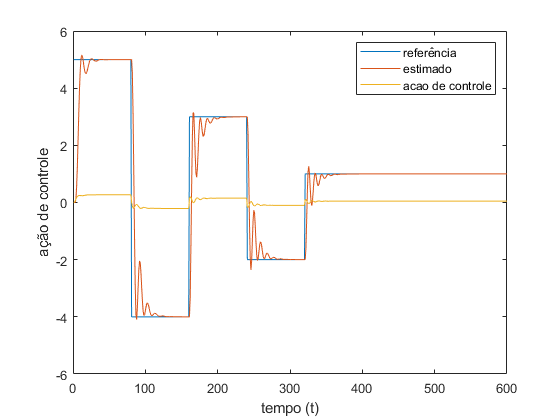

%% resposta do controlador
plot(yref)
hold on 
plot(y,'-')
ylim([-6 6])
hold on
plot(u)
hXLabel = xlabel('tempo (t)'                     );
hYLabel = ylabel('ação de controle'                      );
hLegend = legend('referência','estimado','acao de controle');

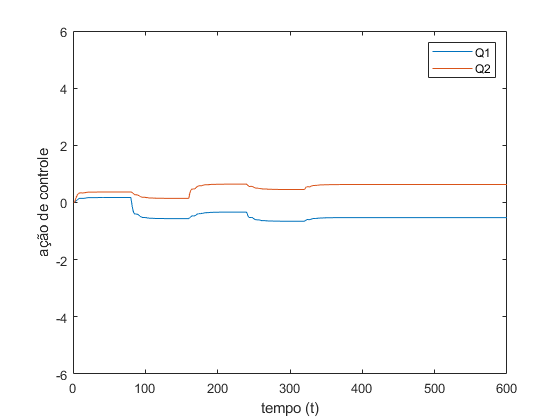


figure
plot(q1)
hold on
plot(q2)
ylim([-6 6])

hXLabel = xlabel('tempo (t)'                     );
hYLabel = ylabel('ação de controle'                      );
hLegend = legend('Q1','Q2');

## Erro Quadratico Médio

% erro quadratico 
nPts = 600;
erro = 0;
for k = 1 :nPts
    erro = erro + (y(k) - yref(k))^2;

end
erro

erro = 628.5262